# Parallel Coordinates

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code loads the data.

X = readmatrix("./data/X.csv");
whos X

  Name        Size            Bytes  Class     Attributes

  X         124x4              3968  double              



## Task 1

The matrix `X` contains 124 observations of 4 variables.

The `kmeans` function can return an optional second output which contains the centroids of each group.

`[``grpNum``,``centroids``]` `=` `kmeans``(``data``,``k``)`

[grp, C] = kmeans(X, 3)

grp =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


C =    -2.7202    6.0202   -1.1364    1.0023
    3.0351   -0.1498    3.1240    1.0116
   -2.2648   -4.0838   -5.2336    1.0035


## Task 2

You can use the [`parallelcoords`](https://www.mathworks.com/help/stats/parallelcoords.html) function to visualize the results.

`parallelcoords``(``data``,``...`

    `"``PropertyName``"``,``PropertyValue``)`

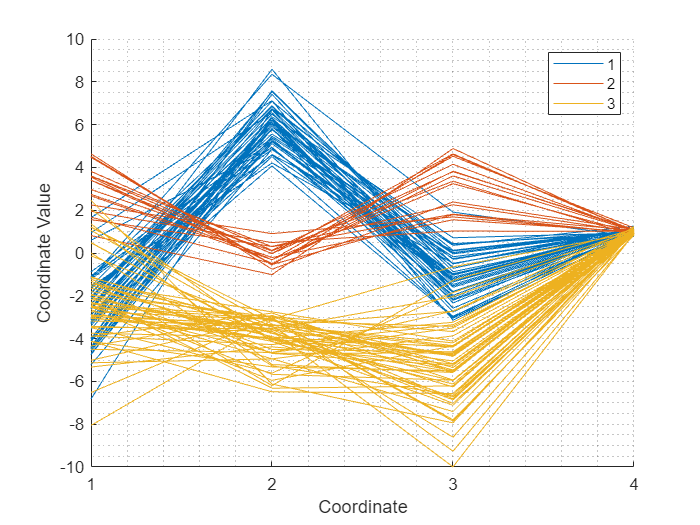

parallelcoords(X, "Group", grp)
grid minor

## Task 3

When you have a large number of observations, visualizing every observation can create clutter. Instead, you can visualize only the centroid of each cluster.

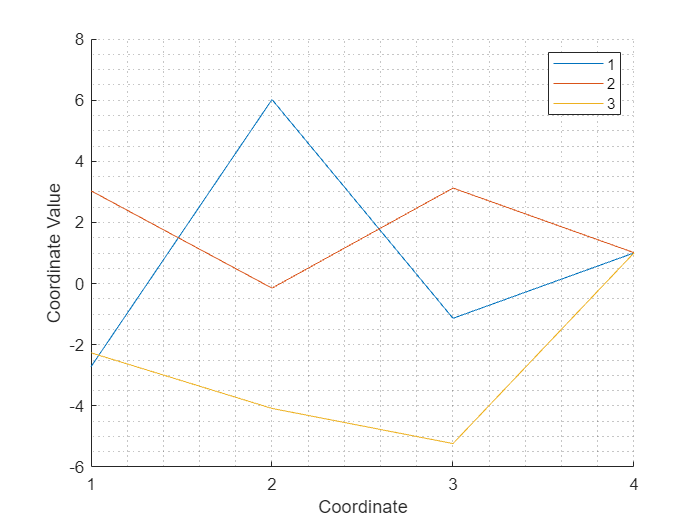

parallelcoords(C, "Group", 1:3)
grid minor

## Task 4

Another option is to plot the median values for each group with bounding lines.

In addition to specifying the `"Group"` property, you can use the `"Quantile"` property with a value between 0 and 1. If you specify the value α, then only the median, α, and 1-α quantile values are plotted for each group.

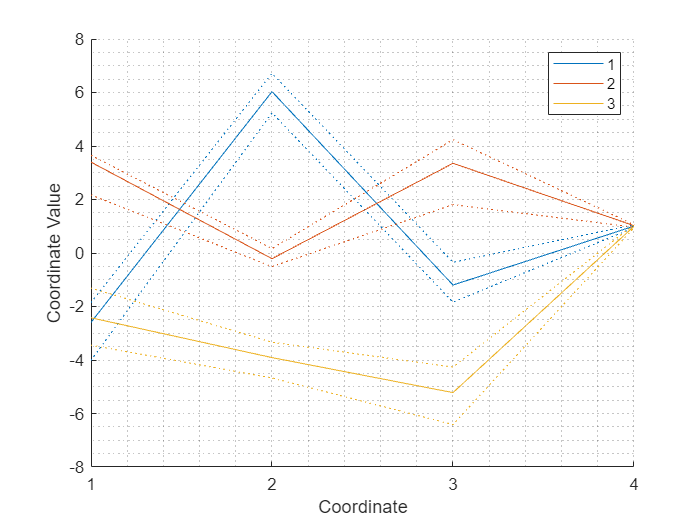

parallelcoords(X, "Group", grp, "Quantile", 0.25)
grid minor